# Phasors

## Overview

- A phasor is a shorthand way of representing a **sinusoidal function**.

- We use a **complex number **to encapsulate both function amplitude and phase.

Phasor Diagram

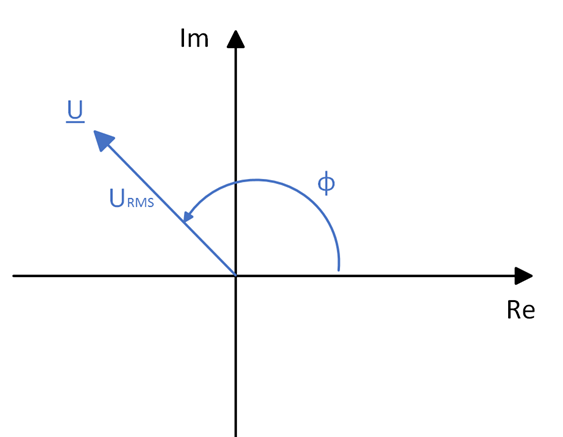

The phasor representation of a sinusoidal voltage (or any other sinusoidal signal) can take many forms:

- Sinusoidal signal: $u\left(t\right)=\sqrt{2}U_{\textrm{RMS}} \;\cos \left(\omega t+\phi \right)$

- Polar form: $\underline{U} =U_{\textrm{RMS}\;} \angle \phi$

- Rectangular form:$\underline{U} =\;\textrm{Re}\;\left\lbrace U_{\textrm{RMS}} \right\rbrace +j\;\textrm{Im}\;\left\lbrace U_{\textrm{RMS}} \right\rbrace =U_{\textrm{RMS}} \;\left(\cos \;\phi +j\;\sin \;\phi \right)$

- Exponential form: $\underline{U} =U_{\textrm{RMS}\;} e^{j\phi }$

Note: In the sinusoidal form, $\phi$ is generally expressed in radians, while in the polar form, $\phi$ is generally expressed in degrees.

## Euler’s identity

To transform a sinusoidal function into a complex variable we use Euler’s identity:

$e^{j\theta } =\cos \;\theta +j\;\sin \;\theta \;$, and thus:

If we take a general sine wave *f(t)*, and an arbitrary complex variable *f**c**(t)*

it can be observed that *f(t)* is *f**c**(t)* real part:

## Phasor forms

As shown in the overview, phasors can be expressed in multiple ways, these are the following forms:

#### Exponential form

#### 

#### **Rectangular form**

#### 

#### **Polar form**

The polar form is expressed by the modulus and the angle (generally in degrees).

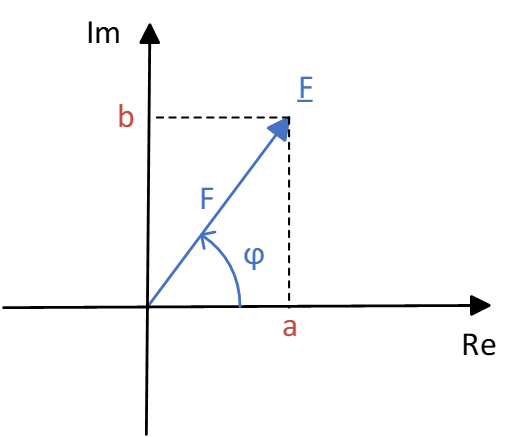

## Nomenclature reminder

As a reminder, it is important to note the difference in the nomenclature.

When expressing a general singal wiht *f(t):*

- instantaneous or time-domain representation,

- is time dependent,

- is always real with no complex term.

When using the expression *F* :

- frequency or phasor-domain representation,

- is not time dependent,

- is generally complex.

Note: 

As seen before, phasor representation omits the term *ω**t*, and hence it can only be used when the variables share the same frequency.

In steady-state AC circuits, all voltage and current signals have the same frequency. 

## Phasor properties

**Additivity**


$$f\left(t\right)=f_1 \left(t\right)+f_2 \left(t\right)\;\iff \;\underline{F} =\underline{F_1 } +\underline{F_2 }$$


**Homogeneity**


$$f\left(t\right)=k\;f_1 \left(t\right)\;\iff \;\underline{F} =k\;\underline{F_1 }$$


**Differentiation**


$$f\left(t\right)=\frac{{d\;f}_1 }{\textrm{dt}}\;\iff \;\underline{F} =j\omega \;\underline{F_1 }$$


**Integration**


$$f\left(t\right)=\int f_1 \left(t\right)\textrm{dt}\;\iff \;\underline{F} =\frac{1}{j\omega }\;\underline{F_1 }$$


## Complex number reminder

- 
$$j=\sqrt{-1}=1\angle 90º$$


- 
$$j^2 =-1=1\angle 180º$$


- 
$$\underline{F} =\;F\angle \phi =a+j\;b$$


- Negative: $-\underline{F} =\;F\angle \left(\phi \pm 180º\right)=-a-j\;b$

- Conjugated: $\underline{F^* } =\;F\angle -\phi =a-j\;b$

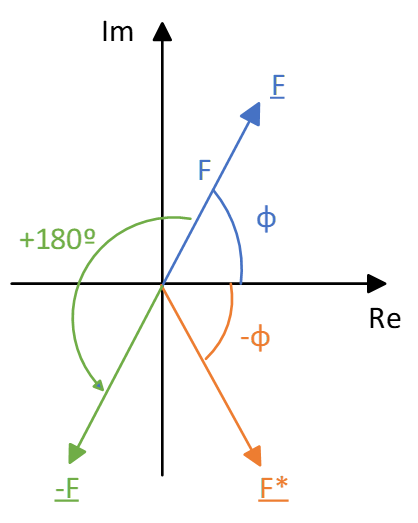

% Matlab representation
z = [3+2i, -3-2i, 3-2i]  % Complex number vector with F, -F and F*

z =    3.0000 + 2.0000i  -3.0000 - 2.0000i   3.0000 - 2.0000i


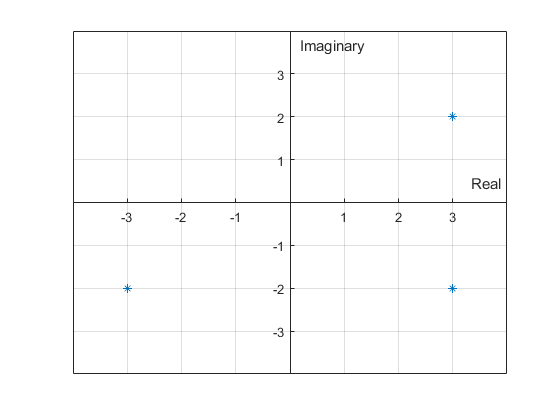

plot(z, '*');
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
xlim([-4.00 4.00])
ylim([-4.00 4.00])
grid on
xlabel('Real')
ylabel('Imaginary')

#### Comlex number based operations

- Sum/subtraction:

- Division/product:

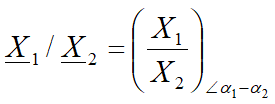,              

- Power:

- Complex conjugate operations:

,    

- Derivative/integrative:

,    

## Phasor visualization

Equivalence phasor – time domain

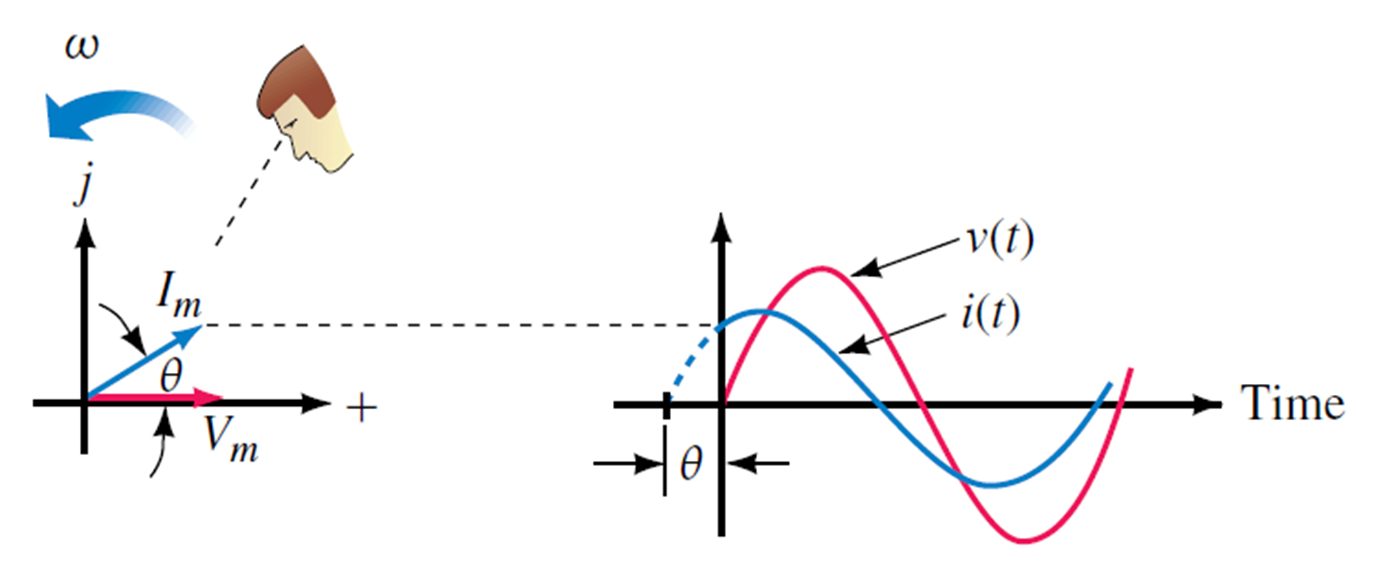

% Time domain+phasor representation of voltage and current across an impedance
close all
clear all
clc

% Definition of frequency (𝜔) and voltage (magnitude and angle)
omega=2*pi*50

omega = 314.1593

Vrms=230

Vrms = 230

Vang=0

Vang = 0

#### Definition load 1 - Polar form

% Impedance in polar form: z=5∠90º
Z=5

Z = 5

Zang=90

Zang = 90

#### Defintion load 2 - Rectangular form

% Impedance in rectangular form: z=a+ib
%  Zreal=0
%  Zimag=5
%  Zcomp=Zreal+i*Zimag
%  Z=abs(Zcomp)
%  Zang=angle(Zcomp)*180/pi

#### Time domain current-voltage

% Phasor exponential form: Fph = Frms*e^jθ (θ in radians)
Vph=Vrms*exp(1i*(Vang*pi/180))

Vph = 230

Zph=Z*exp(1i*(Vang*pi/180))

Zph = 5


% Current I calculation, phasor, magnitude and angle
Iph=Vph/Zph

Iph = 46

Irms=abs(Iph)

Irms = 46

Iang=angle(Iph)*180/pi

Iang = 0


% Time definition, time domain V and I
% f(t)=Frms√2cos(𝜔t+θ)
t=0:0.0001:0.04

t =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


v_t=Vrms*sqrt(2)*cos(omega*t+Vang*pi/180)

v_t =   325.2691  325.1086  324.6273  323.8256  322.7043  321.2645  319.5077  317.4356  315.0502  312.3539  309.3493  306.0395  302.4276  298.5172  294.3123  289.8169  285.0355  279.9728  274.6338  269.0238  263.1482  257.0130  250.6242  243.9880  237.1110  230.0000  222.6620  215.1043  207.3343  199.3597  191.1884  182.8284  174.2879  165.5755  156.6996  147.6691  138.4929  129.1799  119.7395  110.1810  100.5137   90.7472   80.8911   70.9553   60.9494   50.8833   40.7670   30.6105   20.4238   10.2169


i_t=Irms*sqrt(2)*cos(omega*t+Iang*pi/180)

i_t =    65.0538   65.0217   64.9255   64.7651   64.5409   64.2529   63.9015   63.4871   63.0100   62.4708   61.8699   61.2079   60.4855   59.7034   58.8625   57.9634   57.0071   55.9946   54.9268   53.8048   52.6296   51.4026   50.1248   48.7976   47.4222   46.0000   44.5324   43.0209   41.4669   39.8719   38.2377   36.5657   34.8576   33.1151   31.3399   29.5338   27.6986   25.8360   23.9479   22.0362   20.1027   18.1494   16.1782   14.1911   12.1899   10.1767    8.1534    6.1221    4.0848    2.0434


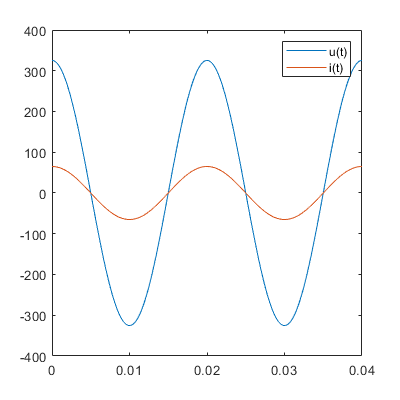


figure('Position',[000 200 400 400])
title('Time domain Voltage and current')
plot(t,v_t)
hold all
plot(t,i_t)
legend('u(t)','i(t)')

#### Current-Voltage phasor

figure('Position',[400 200 400 400])
title('Phasor representation')
axis([-Vrms*1.2,Vrms*1.2 -Vrms*1.2,Vrms*1.2])
line([0,real(Vph)],[0,imag(Vph)],'Color','r')
hold all
line([0,real(Iph)],[0,imag(Iph)],'Color','g')
circle=Vrms*exp(1i*(2*pi*50*t))

circle = 	1.0e+02 *

   2.3000 + 0.0000i   2.2989 + 0.0722i   2.2955 + 0.1444i   2.2898 + 0.2164i   2.2819 + 0.2883i   2.2717 + 0.3598i   2.2593 + 0.4310i   2.2446 + 0.5017i   2.2277 + 0.5720i   2.2087 + 0.6417i   2.1874 + 0.7107i   2.1640 + 0.7791i   2.1385 + 0.8467i   2.1108 + 0.9134i   2.0811 + 0.9793i   2.0493 + 1.0442i   2.0155 + 1.1080i   1.9797 + 1.1708i   1.9420 + 1.2324i   1.9023 + 1.2928i   1.8607 + 1.3519i   1.8174 + 1.4097i   1.7722 + 1.4661i   1.7253 + 1.5210i   1.6766 + 1.5745i   1.6263 + 1.6263i   1.5745 + 1.6766i   1.5210 + 1.7253i   1.4661 + 1.7722i   1.4097 + 1.8174i   1.3519 + 1.8607i   1.2928 + 1.9023i   1.2324 + 1.9420i   1.1708 + 1.9797i   1.1080 + 2.0155i   1.0442 + 2.0493i   0.9793 + 2.0811i   0.9134 + 2.1108i   0.8467 + 2.1385i   0.7791 + 2.1640i   0.7107 + 2.1874i   0.6417 + 2.2087i   0.5720 + 2.2277i   0.5017 + 2.2446i   0.4310 + 2.2593i   0.3598 + 2.2717i   0.2883 + 2.2819i   0.2164 + 2.2898i   0.1444 + 2.2955i   0.0722 + 2.2989i


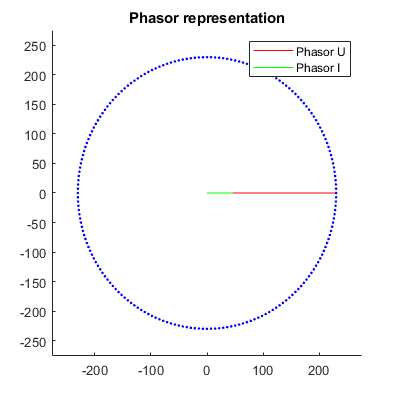

plot(circle,'.','Color','b')
legend('Phasor U','Phasor I')

## Exercise

Transform the following sinusoids to phasors, and phasors to sinusoids:

- 
$$i\left(t\right)=10\;\cos \left(60t+\frac{\pi }{2}\right)\left\lbrack A\right\rbrack$$


- 
$$u\left(t\right)=-220\;\sin \left(50t+\frac{\pi }{4}\right)\left\lbrack V\right\rbrack$$


- 
$$\underline{I} =10\angle 30º\;\left\lbrack A\right\rbrack$$


- 
$$\underline{U} =j\;\left(5-j\;12\right)\left\lbrack V\right\rbrack$$


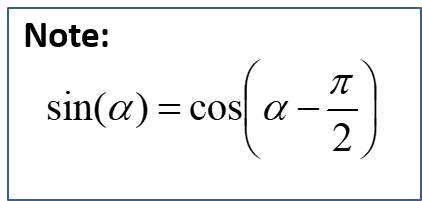

#### Resolution

1. $\underline{I} =10\sqrt{2}\angle 90º\;\left\lbrack A\right\rbrack$

2. $u\left(t\right)=-220\;\sin \left(50t+\frac{\pi }{4}\right)=-220\;\cos \left(50t-\frac{\pi }{4}\right)\left\lbrack V\right\rbrack$

    
$$\underline{U} =\frac{220}{\sqrt{2}}\angle 135º\;\left\lbrack V\right\rbrack \equiv \frac{-220}{\sqrt{2}}\angle -45º\;\left\lbrack V\right\rbrack$$


    To better understand this equivalence it is easier to use a phasor diagram (or use its rectangular form):

        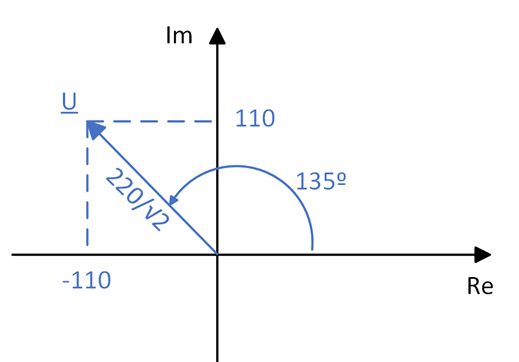                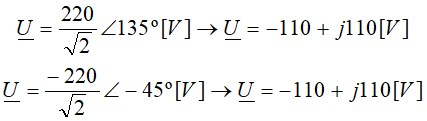                  

3. $i\left(t\right)=10\;\sqrt{2}\cos \left(\omega t+\frac{\pi }{6}\right)\left\lbrack A\right\rbrack$

4. $\underline{U} =j\;\left(5-j\;12\right)=12+j\;5\longrightarrow \underline{U} =13\angle 22\ldotp 62º\;\left\lbrack V\right\rbrack$

    
$$\;u\left(t\right)=13\sqrt{2}\;\cos \left(\omega t-0\ldotp 39\right)\left\lbrack V\right\rbrack$$
